Параметры системы

A = [0 1;
     9 0];
B_1 = [1;
       3];
B_2 = [1;
       0];
C = [1 0;
    0 1;
    0 0];
D = [0; 0; 1];
x_0 = [3; 8];
gamma1 = 2.15;
gamma2 = 3;
gamma3 = 30;

**Проверка системы**

Проверка пары A B на стабилизируемость

U = ctrb(A, B_2);
rankU = rank(U);

Проверка пары Q A на обнаруживаемость

U = obsv(A, C);
rankU = rank(U);
inv(D'*D)

ans = 1

**Первая система**

Матрица регулятора

[Q_1, K_1] = Hinf_controller(A, B_1, B_2, C_2, D_2, gamma1)

Q_1 =   232.2455   86.6031
   86.6031   32.4728


K_1 =  -232.2455  -86.6031


Передаточная функция

sys_1 = ss(A+B_2*K_1, B_1, C_2+D_2*K_1, 0);
[num1, den1] = sys2TfParam(sys_1)

num1 = 3×1 cell array
    {[     0 1.0000 -256.8093]}
    {[           0 3 705.7366]}
    {[0 -492.0548 -1.4762e+03]}


den1 = 3×1 cell array
    {[1 232.2455 770.4278]}
    {[1 232.2455 770.4278]}
    {[1 232.2455 770.4278]}


Вычисление норм

G1 = [tf(num1(1), den1(1));
    tf(num1(2), den1(2));
    tf(num1(3), den1(3))];
disp(norm(G1, 2))

   22.9987



disp(hinfnorm(G1))

    2.1497



**Вторая система**

Матрица регулятора

[Q_2, K_2] = Hinf_controller(A, B_1, B_2, C_2, D_2, gamma2)

Q_2 =    13.1568    4.8364
    4.8364    1.9541


K_2 =   -13.1568   -4.8364


Передаточная функция

sys_2 = ss(A+B_2*K_2, B_1, C_2+D_2*K_2, 0);
[num2, den2] = sys2TfParam(sys_2)

num2 = 3×1 cell array
    {[  0 1.0000 -11.5093]}
    {[        0 3 48.4704]}
    {[0 -27.6661 -82.9983]}


den2 = 3×1 cell array
    {[1 13.1568 34.5279]}
    {[1 13.1568 34.5279]}
    {[1 13.1568 34.5279]}


Вычисление норм

G2 = [tf(num2(1), den2(1));
    tf(num2(2), den2(2));
    tf(num2(3), den2(3))];
disp(norm(G2, 2))

    6.3073



disp(hinfnorm(G2))

    2.8036



**Третья система**

Матрица регулятора

[Q_3, K_3] = Hinf_controller(A, B_1, B_2, C_2, D_2, gamma3)

Q_3 =     6.7002    2.4264
    2.4264    1.0523


K_3 =    -6.7002   -2.4264


Передаточная функция

sys_3 = ss(A+B_2*K_3, B_1, C_2+D_2*K_3, 0);
[num3, den3] = sys2TfParam(sys_3)

num3 = 3×1 cell array
    {[        0 1 -4.2792]}
    {[        0 3 29.1006]}
    {[0 -13.9794 -41.9382]}


den3 = 3×1 cell array
    {[1 6.7002 12.8377]}
    {[1 6.7002 12.8377]}
    {[1 6.7002 12.8377]}


Вычисление норм

G3 = [tf(num3(1), den3(1));
    tf(num3(2), den3(2));
    tf(num3(3), den3(3))];
disp(norm(G3, 2))

    5.5302



disp(hinfnorm(G3))

    3.9902



**Построение графиков**

График сингулярных чисел

% sigma(sys_1);
% hold on;
% grid on;
% sigma(sys_2);
% hold on;
% sigma(sys_3);
% legend('σ1', 'σ2', 'σ3');
% hold off;

Покомпонентные АЧХ системы

% bodemag(sys_1);
% hold on;
% grid on;
% bodemag(sys_2);
% hold on;
% bodemag(sys_3);
% legend('System 1', 'System 2', 'System 3');
% hold off;

**Графики с возмушающим воздействием**

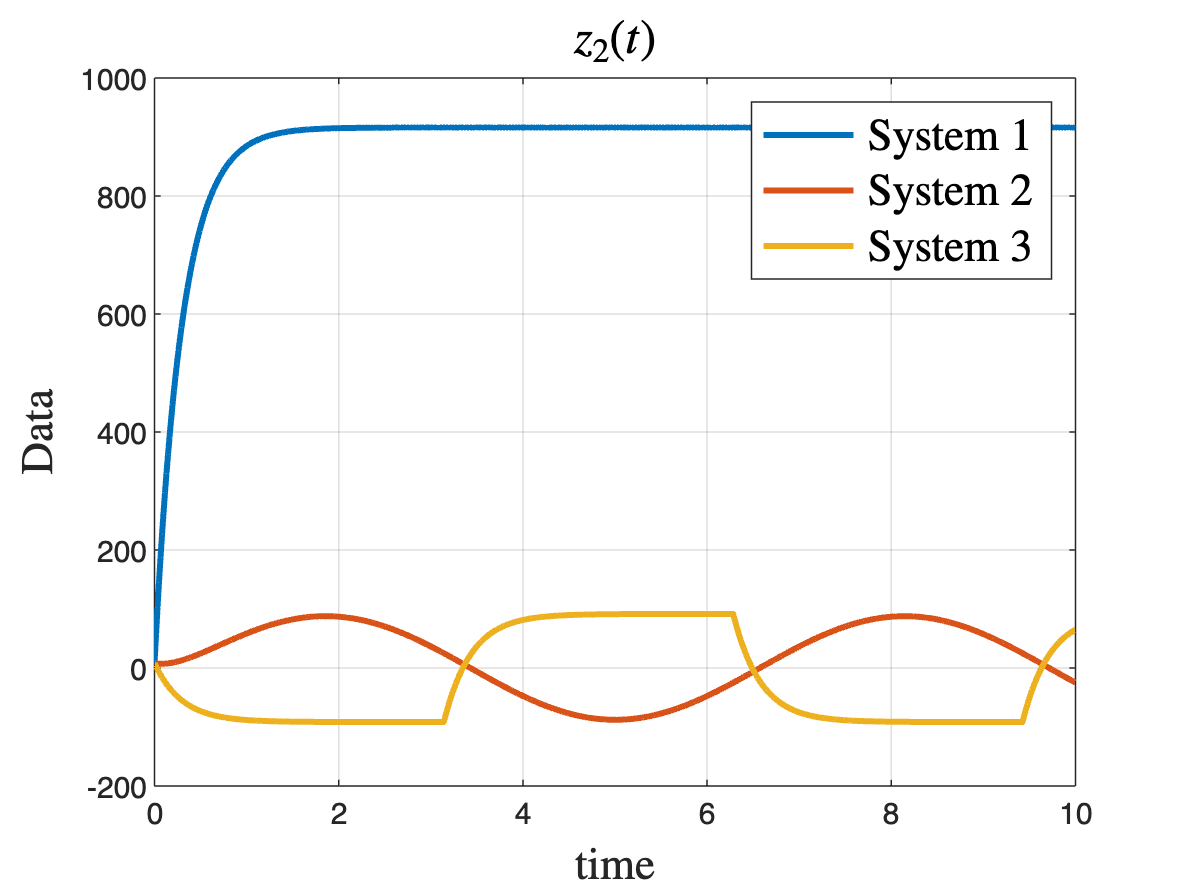

plot(out.z.Time, out.z.Data(:, 1), LineWidth=2.0);
hold on;
plot(out.z1.Time, out.z1.Data(:, 1), LineWidth=2.0);
title('$z_{1}(t)$','Interpreter', 'latex', 'FontSize', 16);
xlabel('time', 'Interpreter', 'latex', 'FontSize', 15);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
legend('System 1', 'System 2', 'Interpreter', 'latex', 'FontSize', 15);
grid on;

hold off;
plot(out.z.Time, out.z.Data(:, 2), LineWidth=2.0);
hold on;
plot(out.z1.Time, out.z1.Data(:, 2), LineWidth=2.0);
title('$z_{2}(t)$','Interpreter', 'latex', 'FontSize', 16);
xlabel('time', 'Interpreter', 'latex', 'FontSize', 15);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
legend('System 1', 'System 2', 'Interpreter', 'latex', 'FontSize', 15);
grid on;

hold off;

plot(out.z.Time, out.z.Data(:, 3), LineWidth=2.0);
hold on;
plot(out.z1.Time, out.z1.Data(:, 3), LineWidth=2.0);
grid on;
title('$z_{u}(t)$','Interpreter', 'latex', 'FontSize', 16);
xlabel('time', 'Interpreter', 'latex', 'FontSize', 15);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
legend('System 1', 'System 2', 'Interpreter', 'latex', 'FontSize', 15);
